% /this is the full code % Step 1: Download file
url = 'https://github.com/geastho/AtmosphericRiver_predictive_skill_2025/raw/main/ht_matched_final.nc';
filename = 'ht_matched_final.nc';
websave(filename, url);

% Step 2: Read NetCDF data
ncdisp(filename) % to see variables

Source:
           /Users/gretaeasthom/Downloads/Wk12_MATLAB-20250411/ht_matched_final.nc
Format:
           netcdf4
Dimensions:
           y    = 56
           x    = 56
           time = 849
Variables:
    lon     
           Size:       56x1
           Dimensions: y
           Datatype:   double
           Attributes:
                       _FillValue = NaN
    lat     
           Size:       56x1
           Dimensions: x
           Datatype:   double
           Attributes:
                       _FillValue = NaN
    time    
           Size:       849x1
           Dimensions: time
           Datatype:   int64
           Attributes:
                       units    = 'days since 1985-12-08 00:00:00'
                       calendar = 'proleptic_gregorian'
    variable
           Size:       56x56x849
           Dimensions: x,y,time
           Datatype:   double
           Attributes:
                       _FillValue  = NaN
                       coordinates = 'lat lon'


height = ncread(filename, 'variable'); % replace VARIABLE_NAME appropriately

% 



url = 'https://github.com/geastho/AtmosphericRiver_predictive_skill_2025/raw/main/regridwrfss_matched_0605.nc';
subset= 'regridwrfss_matched_0605.nc';
websave(subset, url);

ncdisp(subset)

Source:
           /Users/gretaeasthom/Downloads/Wk12_MATLAB-20250411/regridwrfss_matched_0605.nc
Format:
           netcdf4
Dimensions:
           time = 851
           x    = 56
           y    = 56
Variables:
    variable
           Size:       56x56x851
           Dimensions: y,x,time
           Datatype:   double
           Attributes:
                       _FillValue  = NaN
                       coordinates = 'lat lon'
    lon     
           Size:       56x851
           Dimensions: y,time
           Datatype:   double
           Attributes:
                       _FillValue = NaN
    lat     
           Size:       56x851
           Dimensions: x,time
           Datatype:   double
           Attributes:
                       _FillValue = NaN
    time    
           Size:       851x1
           Dimensions: time
           Datatype:   int64
           Attributes:
                       units    = 'days since 1985-12-08 00:00:00'
                       calendar = 'proleptic_gre

subsetarray=ncread(subset,'variable')

subsetarray = subsetarray(:,:,1) =

   1.0e+03 *

    0.1928    0.1938    0.1843    0.1841    0.1757    0.1641    0.1613    0.1662    0.1732    0.1667    0.1568    0.1478    0.1424    0.1375    0.1291    0.1240    0.1193    0.1166    0.1096    0.1152    0.1056    0.1049    0.1068    0.0972    0.0901    0.0949    0.0851    0.0920    0.0843    0.0818    0.0808    0.0737    0.0689    0.0697    0.0649    0.0599    0.0636    0.0562    0.0574    0.0587    0.0618    0.0666    0.0684    0.0636    0.0690    0.0806    0.0964    0.1206    0.1393    0.1402    0.1427    0.1500    0.1592    0.1393    0.1492    0.1660
    0.1906    0.1929    0.1948    0.1857    0.1843    0.1747    0.1685    0.1651    0.1771    0.1742    0.1612    0.1567    0.1497    0.1434    0.1402    0.1272    0.1229    0.1246    0.1136    0.1211    0.1188    0.1088    0.1061    0.0995    0.0948    0.1023    0.0952    0.0898    0.0791    0.0766    0.0732    0.0675    0.0624    0.0609    0.0630    0.0631    0.0717    0.0601    0.058


subsetarray_reshaped = reshape(subsetarray, [], size(subsetarray, 3))';  % [time, lat*lon]





% Step 3: Normalize each row (each time step)
data = normalize(subsetarray_reshaped, 2);  % [849 x 3136], normalized across each row




% Step 4: Setup SOM
som_grid_rows = 4;
som_grid_columns = 4;

net = selforgmap([som_grid_columns som_grid_rows], 100, 3);  % [cols rows], 100 steps, neighborhood size 3




% Step 5: Configure SOM properties
net.trainParam.lr = 0.5;                      % Learning rate
net.trainParam.epochs = 100000;               % Max epochs
net.trainParam.showWindow = true;             % Show GUI (optional)
net.layers{1}.topologyFcn = 'gridtop';        % Rectangular grid
net.layers{1}.distanceFcn = 'dist';           % Euclidean distance



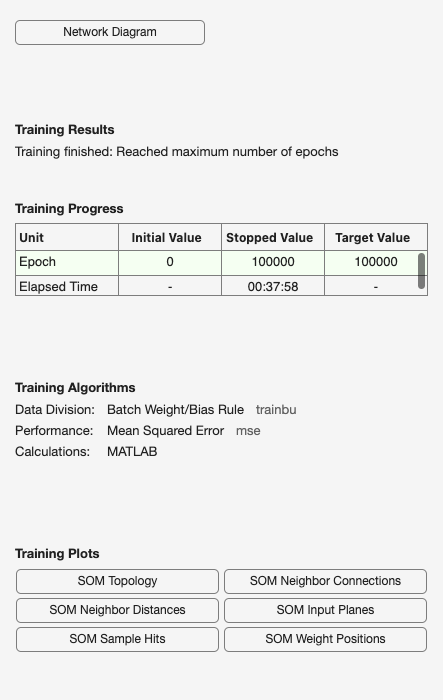


% Step 6: Train SOM
rng(1)
% Transpose data to [features x samples] = [3136 x 849]
net = train(net, data');


% subsetarray_reshaped = reshape(subsetarray_norm, [], size(subsetarray_norm, 3))'; 
% 
% data = normalize(subsetarray_reshaped, 2);  % normalize each sample (row)
% 
% 
% 
% % Normalize the data
% subsetarray_norm = normalize(subsetarray, 2); % Normalize across each row

% 
% 
% % Step 4: SOM Setup
% som_grid_rows = 4;
% som_grid_columns = 4;
% input_length = size(subsetarray_norm, 2);

% 
% 
% net = selforgmap([som_grid_columns som_grid_rows], 100);
% net.trainParam.lr = 0.5; 
% net.layers{1}.topologyFcn = 'gridtop';   % rectangular SOM grid
% net.layers{1}.distanceFcn = 'dist'; 
% net.trainParam.epochs = 100000;
% net.trainParam.showWindow = true;


% 
% % Set random seed
% rng(1);
% 
% % Step 5: Train SOM
% net = train(net, subsetarray_norm');



% Step 6: Find Winning Neurons
outputs = net(data');
positions = vec2ind(outputs);




% Map positions to SOM grid
winmap = cell(som_grid_rows, som_grid_columns);
for i = 1:length(positions)
    [row, col] = ind2sub([som_grid_columns, som_grid_rows], positions(i));
    winmap{col, row}(end+1) = i;  % Be careful MATLAB indexes (row, col)
end


% 
% figure;
% for r = 1:som_grid_rows
%     for c = 1:som_grid_columns
%         subplot(som_grid_rows, som_grid_columns, (r-1)*som_grid_columns + c);
% 
%         % Find the indices that map to this SOM node
%         indices = winmap{r, c};
% 
%         if ~isempty(indices)
%             % Use the reshaped/normalized data from earlier (not the original 3D)
%             temp_data = mean(data(indices, :), 1);  % [1 x 3136]
%             %temp_data =3
%             % Reshape back to spatial grid [56 x 56]
%             %temp_map = reshape(temp_data, 56, 56); 
%             %temp_map = reshape(temp_data, 56, 56)';
% 
%             % ht_data=mean(height(indices, :), 1);
%             % temp_ht=reshape(ht_data,56,56)
% 
%             % ht_data = mean(height(:, :, indices), 3);
%             % 
%             % [C, h] = contour(ht_data, 'k');  % black contours
%             % clabel(C, h, 'FontSize', 6);  % optional: label contour values
% 
%             x = 1:56;                          % X-axis = grid columns
%             %y = linspace(0, 800, 56); % Y-axis = height from 0 to 800
%             y= 1:56;
% 
%             % cmin = min(subsetarray_reshaped(:));
%             % cmax = max(subsetarray_reshaped(:));
% 
%             % Plot the composite
%             imagesc(x,y,temp_data, [250,800]);
%             title(['Sample size: ' num2str(length(indices))]);
%             axis xy tight;
%             ylim([0 800]);  % set y-axis limit
%             colorbar;
%         else
%             % Optional: indicate no samples hit this node
%             title('No data');
%         end
%     end
% end
% saveas(gcf, 'som_moisture_ex_new.png');
% 
% sgtitle('Moisture-trained SOM composites');


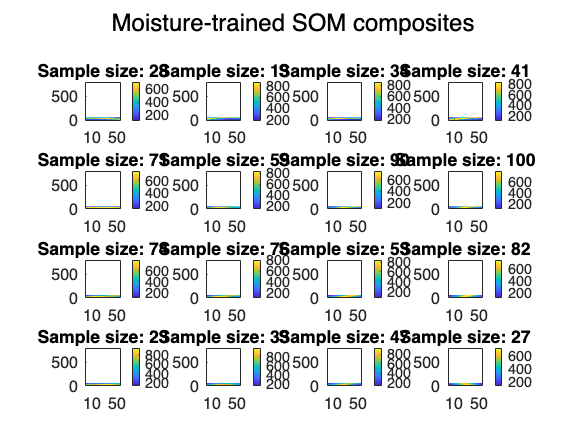

figure;
for r = 1:som_grid_rows
    for c = 1:som_grid_columns
        subplot(som_grid_rows, som_grid_columns, (r-1)*som_grid_columns + c);
        indices = winmap{r, c};

        if ~isempty(indices)
            temp_data = mean(subsetarray_reshaped(indices, :), 1);  % average across time
            temp_map = reshape(temp_data, 56, 56)';  % transpose for correct orientation

            x = 1:56; y = 1:56;
            imagesc(x, y, temp_map);
            axis xy tight;
            title(['Sample size: ' num2str(length(indices))]);
            colorbar;
        else
            title('No data');
        end
    end
end
sgtitle('Moisture-trained SOM composites');
saveas(gcf, 'som_moisture_ex_newest.png');

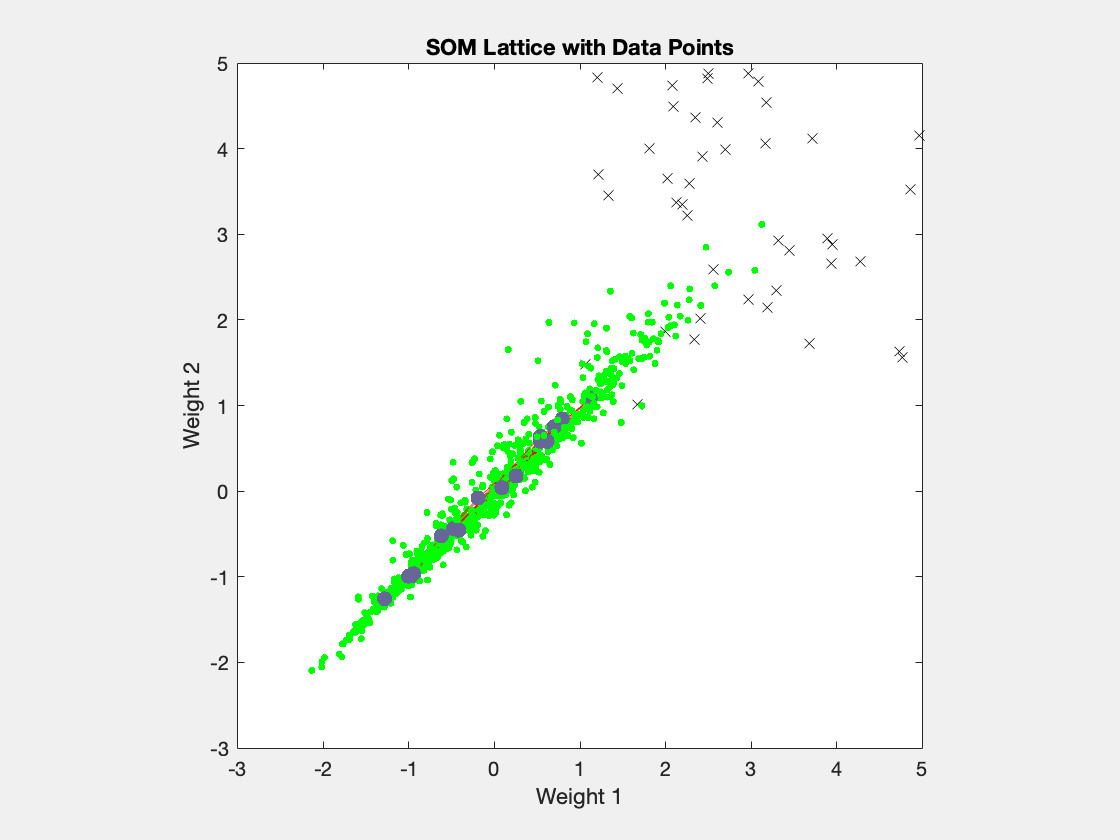



% Step 8: Plot SOM lattice + scatter data points
figure;
%plotsom(net.iw{1,1}, net.layers{1}.distances)
plotsompos(net, data')
title('SOM Lattice with Data Points');
hold on;

% Overplot where each input fell
for i = 1:20:length(positions)
    [row, col] = ind2sub([som_grid_columns, som_grid_rows], positions(i));
    scatter(col + rand(), row + rand(), 'kx');
end
hold off;


size(height)

ans =     56    56   849


% Visualize weights for feature 500 (for example)
plane = reshape(net.IW{1}( :, 500 ), som_grid_rows, som_grid_columns);
imagesc(plane);
colorbar;
title('Component plane for feature 500');